# Plot experimental data in the composition space

## Import the datasets that contain the experimental data

addpath('./modules_pp')
path=getenv('DATASETS_DIR');
disp(path)

A:\PUBLI_CONF\PUBLICATION\datasets\


compo_properties=readtable(path+"Data_averaged.csv");


compo_properties=compo_properties(:,2:end); % suppress first column and keep only compositions and outputs
compo_m=table2array(compo_properties(:,7:11))/100;
E=table2array(compo_properties(:,12));
H=table2array(compo_properties(:,13));
class_EBSD=table2array(compo_properties(:,18));

compo_XRD=readtable(path+"Database_XRD.csv");

compo_m_XRD=table2array(compo_XRD(:,8:12))/100;
class_XRD=table2array(compo_XRD(:,13));


## Prepare composition space plotting

nb_elements=5;
name_elements=["Zr","Nb","Mo","Ti","Cr"];

x = gallery('uniformdata',[nb_elements 1],0);
y = gallery('uniformdata',[nb_elements 1],1);
z = gallery('uniformdata',[nb_elements 1],2);
DT = delaunayTriangulation(x,y,z);
[T,Xb] = freeBoundary(DT);
TR = triangulation(T,Xb);
F = faceNormal(TR);

### Mixture Design point: coordinates generation

mixtures={[x,y,z]};
name_mixture={transpose(name_elements)};
nb_mixtures=nb_elements;
combinatorial_basis=[1:nb_elements]; 

for k=2:nb_elements
    combinatorial_mixture=nchoosek(combinatorial_basis,k); % liste des éléments des mélanges à k élements
    x_mixture=[];
    y_mixture=[];
    z_mixture=[];
    name=[];
    for i=1:size(combinatorial_mixture,1)
        x_mixture=[x_mixture;1/k*sum(x(combinatorial_mixture(i,:)))]; % coordonnées des mélanges à k éléments
        y_mixture= [y_mixture;1/k*sum(y(combinatorial_mixture(i,:)))];
        z_mixture= [z_mixture;1/k*sum(z(combinatorial_mixture(i,:)))];
        name=[name;strjoin(name_elements(combinatorial_mixture(i,:)),'')];
    end
    
    mixtures{end+1}=[x_mixture,y_mixture,z_mixture];
    nb_mixtures=nb_mixtures + size(x_mixture,1);
    name_mixture{end+1}="  "+name;
   
    
end

## Coordinates of experimental points


coord_m=[compo_m*x,compo_m*y,compo_m*z];
coord_m_XRD=[compo_m_XRD*x,compo_m_XRD*y,compo_m_XRD*z];


## Color scales for E and H

color=hot;

E_scaled=(E-min(E))/(max(E)-min(E));
color_index_E=(round(E_scaled.*255)+1);

H_scaled=(H-min(H))/(max(H)-min(H));
color_index_H=(round(H_scaled.*255)+1);
color_index_EBSD=255-class_EBSD.*255+1;
color_index_XRD=255-class_XRD.*255+1;

## Plot figures

Plot elastic modulus values

figure('position', [80, 80, 1000, 1000])
set(gca,'DefaultTextFontName','Helvetica','DefaultTextFontSize', 16)
set(gca,'color','w')
hold on
tetramesh(DT,'FaceAlpha',0.05);
text(TR.Points(:,1),TR.Points(:,2),TR.Points(:,3),name_elements)

for i=2:nb_elements
    plot3(mixtures{i}(:,1),mixtures{i}(:,2),mixtures{i}(:,3),'dk','MarkerFaceColor','k','MarkerSize',10)
    text(mixtures{i}(:,1),mixtures{i}(:,2),mixtures{i}(:,3),name_mixture{i})
end

for i=1:size(E,1)
    plot3(coord_m(i,1),coord_m(i,2),coord_m(i,3),'ok-','MarkerFaceColor',color(color_index_E(i),:),'MarkerSize',E(i)./25)
end

view(45,0)
OptionZ.FrameRate=30;OptionZ.Duration=10;OptionZ.Periodic=true;
angles=-1*[20:50:380];

angles =    -20   -70  -120  -170  -220  -270  -320  -370


position=[10,10,30,40,35,30,10,10];

position =     10    10    30    40    35    30    10    10


ViewZ=[angles',position'];

ViewZ =    -20    10
   -70    10
  -120    30
  -170    40
  -220    35
  -270    30
  -320    10
  -370    10


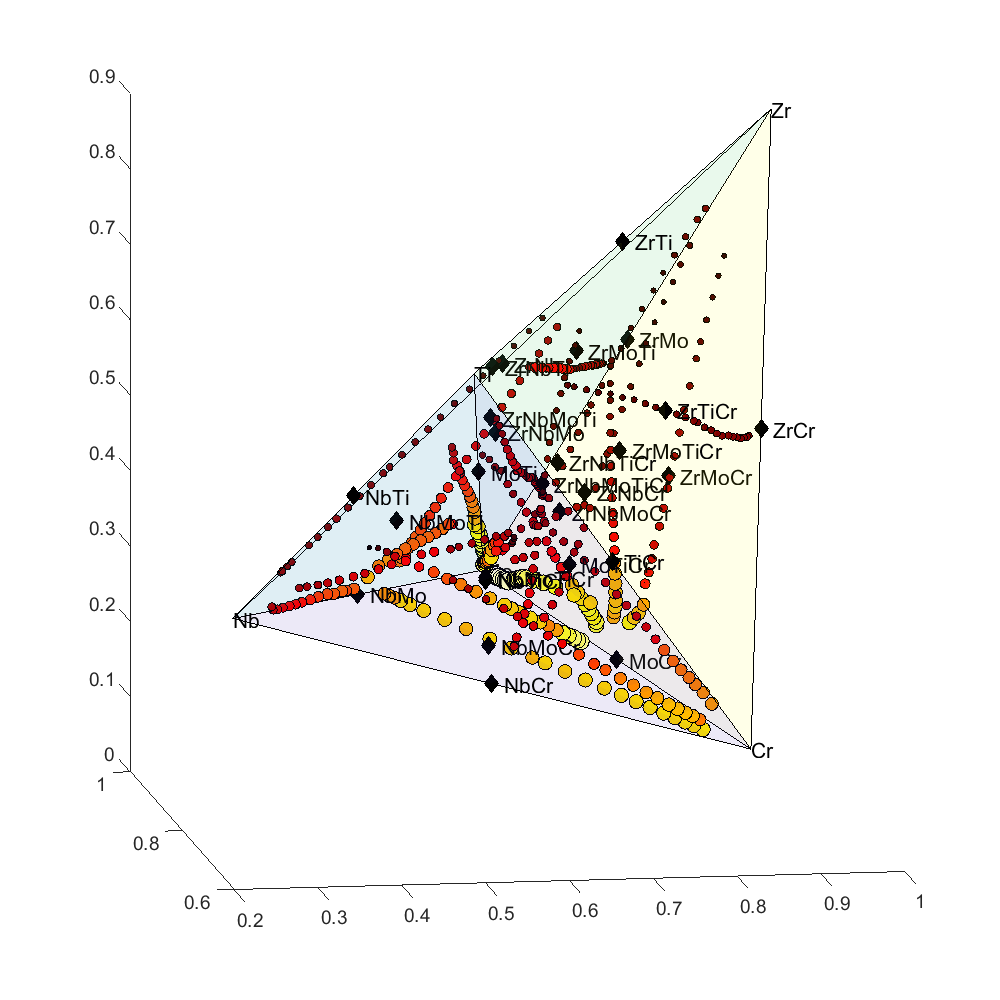

CaptureFigVid(ViewZ,'E',OptionZ);

Plot Hardness values

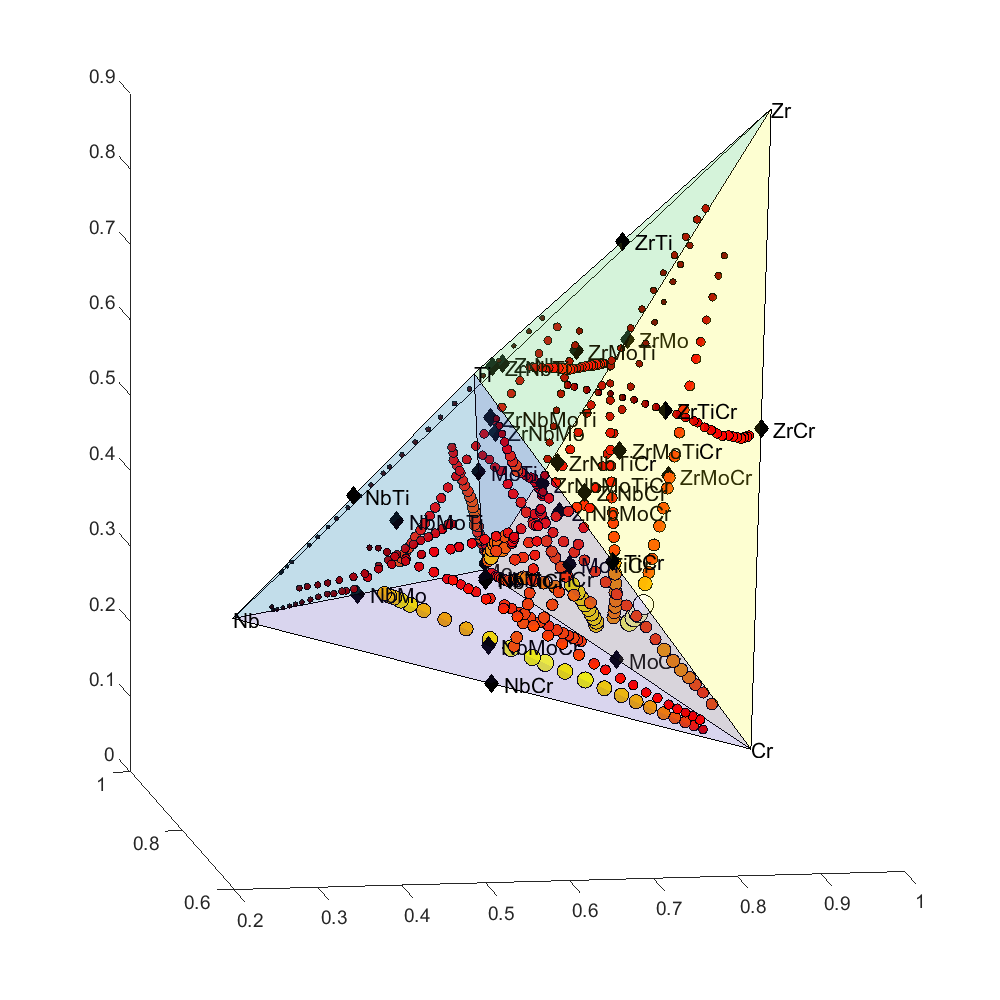

figure('position', [80, 80, 1000, 1000])
set(gca,'DefaultTextFontName','Helvetica','DefaultTextFontSize', 16)
set(gca,'color','w')
hold on
tetramesh(DT,'FaceAlpha',0.10);
text(TR.Points(:,1),TR.Points(:,2),TR.Points(:,3),name_elements)

for i=2:nb_elements
    plot3(mixtures{i}(:,1),mixtures{i}(:,2),mixtures{i}(:,3),'dk','MarkerFaceColor','k','MarkerSize',10)
    text(mixtures{i}(:,1),mixtures{i}(:,2),mixtures{i}(:,3),name_mixture{i})
end

for i=1:size(H,1)
    plot3(coord_m(i,1),coord_m(i,2),coord_m(i,3),'ok-','MarkerFaceColor',color(color_index_H(i),:),'MarkerSize',H(i)./1.5)
end

view(45,0)


Plot EBSD class values

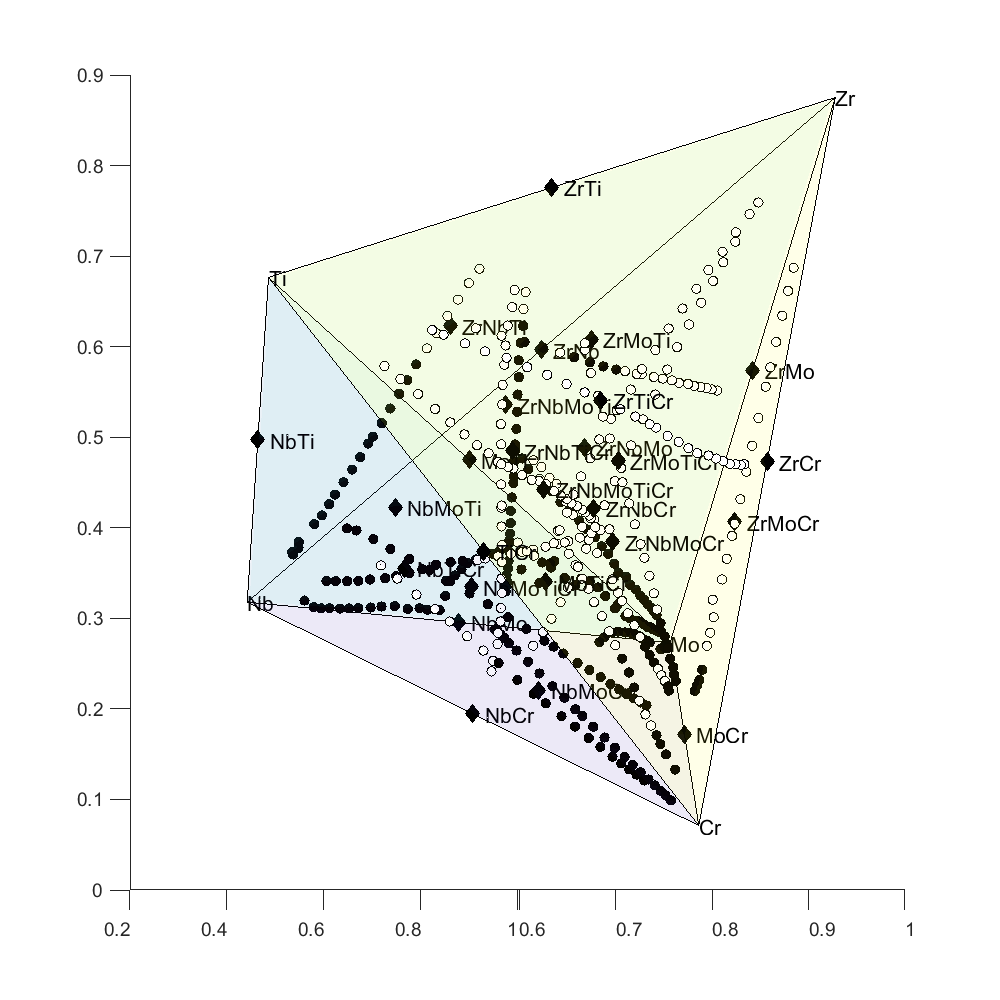

figure('position', [80, 80, 1000, 1000])
set(gca,'DefaultTextFontName','Helvetica','DefaultTextFontSize', 16)
set(gca,'color','w')
hold on
tetramesh(DT,'FaceAlpha',0.05);
text(TR.Points(:,1),TR.Points(:,2),TR.Points(:,3),name_elements)

for i=2:nb_elements
    plot3(mixtures{i}(:,1),mixtures{i}(:,2),mixtures{i}(:,3),'dk','MarkerFaceColor','k','MarkerSize',10)
    text(mixtures{i}(:,1),mixtures{i}(:,2),mixtures{i}(:,3),name_mixture{i})
end

for i=1:size(H,1)
    plot3(coord_m(i,1),coord_m(i,2),coord_m(i,3),'ok-','MarkerFaceColor',color(color_index_EBSD(i),:),'MarkerSize',7)
end

view(45,0)

Plot XRD class values

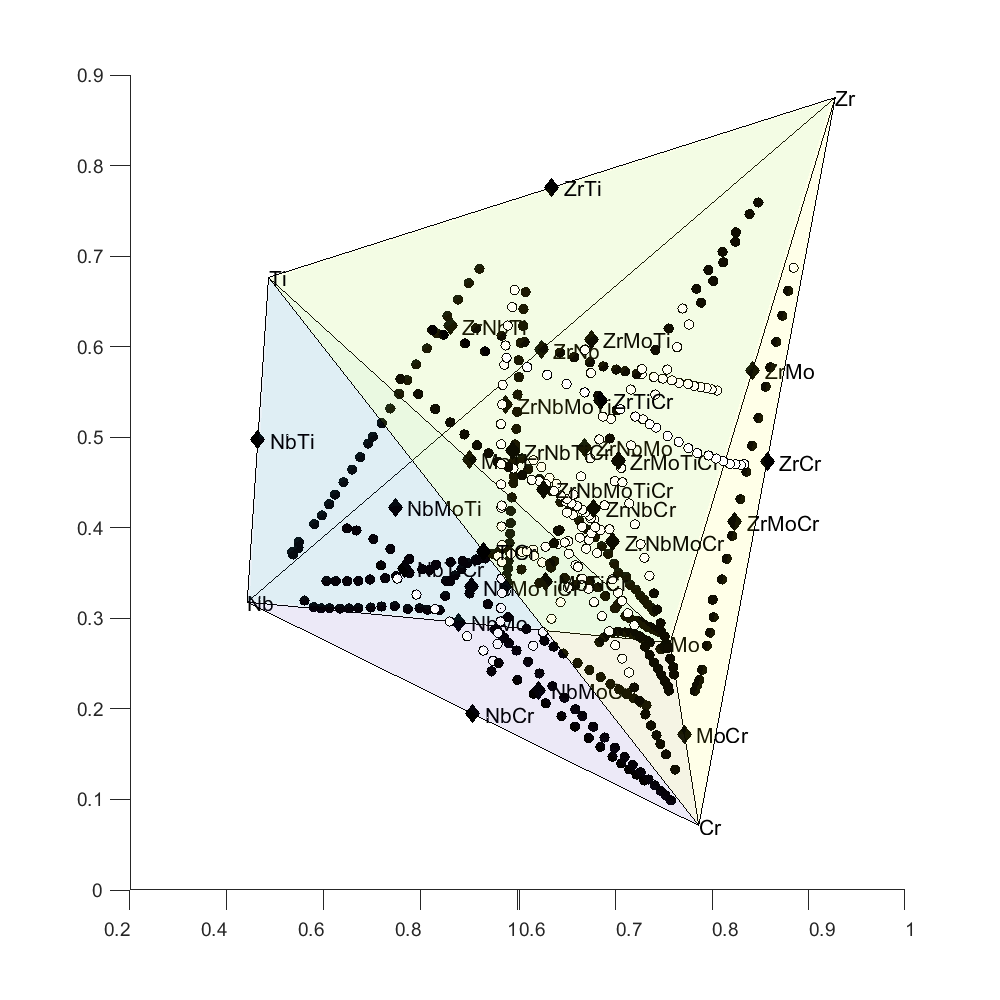

figure('position', [80, 80, 1000, 1000])
set(gca,'DefaultTextFontName','Helvetica','DefaultTextFontSize', 16)
set(gca,'color','w')
hold on
tetramesh(DT,'FaceAlpha',0.05);
text(TR.Points(:,1),TR.Points(:,2),TR.Points(:,3),name_elements)

for i=2:nb_elements
    plot3(mixtures{i}(:,1),mixtures{i}(:,2),mixtures{i}(:,3),'dk','MarkerFaceColor','k','MarkerSize',10)
    text(mixtures{i}(:,1),mixtures{i}(:,2),mixtures{i}(:,3),name_mixture{i})
end

for i=1:size(class_XRD,1)
    plot3(coord_m_XRD(i,1),coord_m_XRD(i,2),coord_m_XRD(i,3),'ok-','MarkerFaceColor',color(color_index_XRD(i),:),'MarkerSize',7 )
end

view(45,0)

## Expected vs experimental gradients

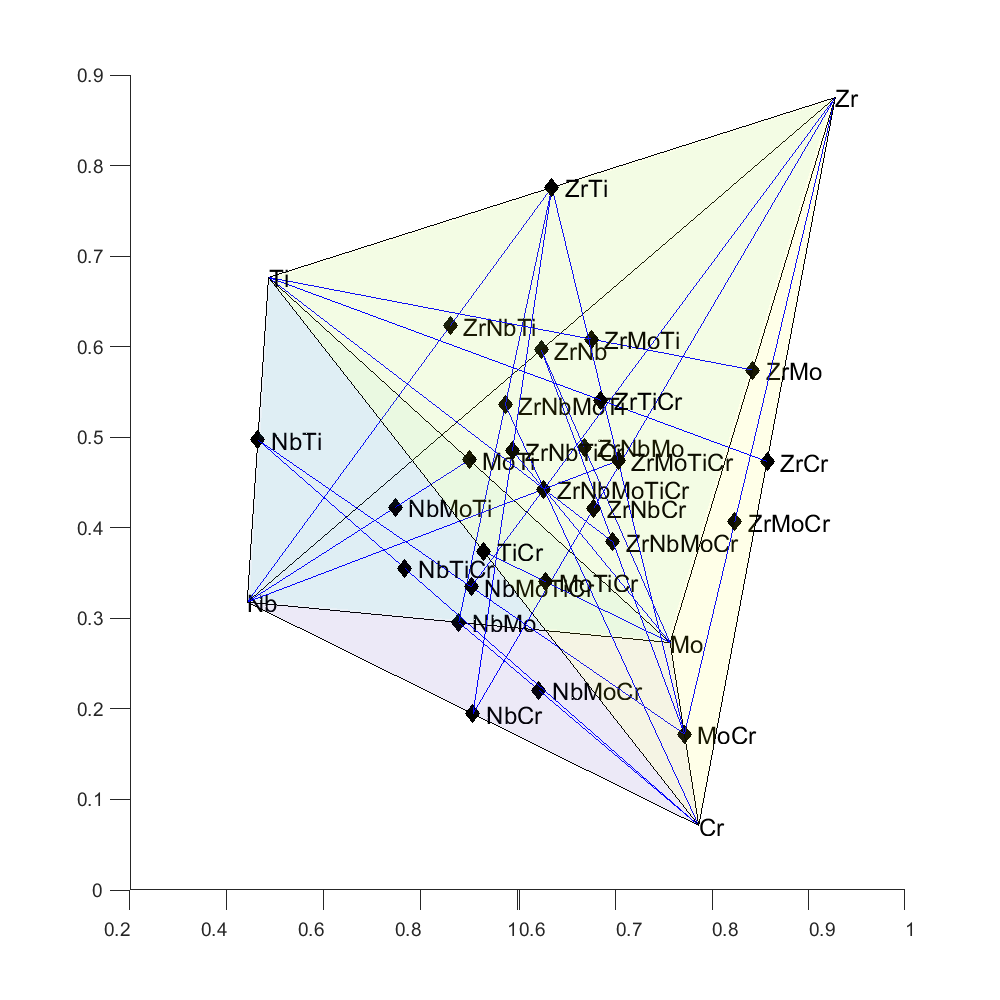

align_main=[mixtures{1}(5,:),mixtures{5}(1,:),mixtures{4}(1,:); %Cr-NbTiZrMo
             mixtures{1}(4,:),mixtures{5}(1,:),mixtures{4}(2,:); % Ti-NbZrCrMo
             mixtures{1}(3,:),mixtures{5}(1,:),mixtures{4}(3,:); % Mo - NbTiZrCr
             mixtures{1}(2,:),mixtures{5}(1,:),mixtures{4}(4,:); % Nb - TiZrCrMo
             mixtures{1}(1,:),mixtures{5}(1,:),mixtures{4}(5,:); % Zr - NbTiCrMo
             mixtures{1}(2,:),mixtures{3}(2,:),mixtures{2}(3,:); % Nb -ZrTi
             mixtures{1}(2,:),mixtures{3}(7,:),mixtures{2}(8,:); % Nb - MoTi
             mixtures{1}(5,:),mixtures{3}(9,:),mixtures{2}(6,:); % Cr - NbTi
             mixtures{1}(5,:),mixtures{3}(8,:),mixtures{2}(5,:); % Cr - NbMo
             mixtures{1}(1,:),mixtures{3}(3,:),mixtures{2}(7,:); % Zr - NbCr
             mixtures{1}(1,:),mixtures{3}(5,:),mixtures{2}(9,:); % Zr - MoCr
             mixtures{1}(3,:),mixtures{3}(10,:),mixtures{2}(10,:); % Mo - TiCr
             mixtures{1}(3,:),mixtures{3}(1,:),mixtures{2}(1,:); % Mo - ZrNb
             mixtures{1}(4,:),mixtures{3}(6,:),mixtures{2}(4,:); % Ti - ZrCr
             mixtures{1}(4,:),mixtures{3}(4,:),mixtures{2}(2,:); % Ti - ZrMo
             mixtures{2}(3,:),mixtures{4}(2,:),mixtures{2}(9,:); % ZrTi - MoCr
             mixtures{2}(1,:),mixtures{4}(2,:),mixtures{2}(9,:); %  ZrNb - MoCr
             mixtures{2}(6,:),mixtures{4}(2,:),mixtures{2}(9,:); % NbTi - MoCr
             mixtures{2}(5,:),mixtures{4}(2,:),mixtures{2}(3,:); % NbMo - ZrTi
             mixtures{2}(7,:),mixtures{4}(2,:),mixtures{2}(3,:)]; % NbCr - ZrTi
    
figure('position', [80, 80, 1000, 1000])
set(gca,'DefaultTextFontName','Helvetica','DefaultTextFontSize', 18)
set(gca,'color','w')
hold on
tetramesh(DT,'FaceAlpha',0.05);
text(TR.Points(:,1),TR.Points(:,2),TR.Points(:,3),name_elements)


for i=2:nb_elements
    plot3(mixtures{i}(:,1),mixtures{i}(:,2),mixtures{i}(:,3),'dk','MarkerFaceColor','k','MarkerSize',10)
    text(mixtures{i}(:,1),mixtures{i}(:,2),mixtures{i}(:,3),name_mixture{i})
end

for i=1:size(align_main,1)
    plot3([align_main(i,1),align_main(i,7)],[align_main(i,2),align_main(i,8)],[align_main(i,3),align_main(i,9)],'b')
end
view(45,0)

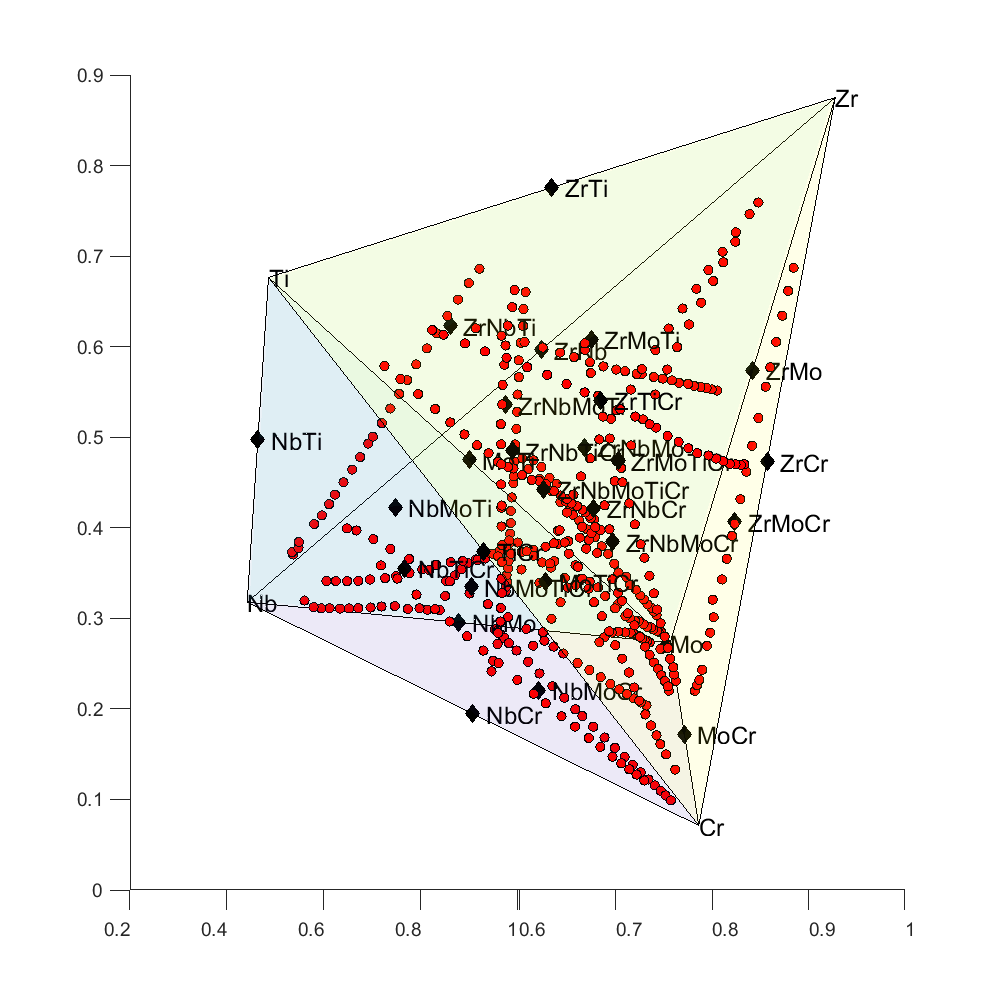


figure('position', [80, 80, 1000, 1000])
set(gca,'DefaultTextFontName','Helvetica','DefaultTextFontSize', 18)
set(gca,'color','w')
hold on
tetramesh(DT,'FaceAlpha',0.05);
text(TR.Points(:,1),TR.Points(:,2),TR.Points(:,3),name_elements)


for i=2:nb_elements
    plot3(mixtures{i}(:,1),mixtures{i}(:,2),mixtures{i}(:,3),'dk','MarkerFaceColor','k','MarkerSize',10)
    text(mixtures{i}(:,1),mixtures{i}(:,2),mixtures{i}(:,3),name_mixture{i})
end

for i=1:size(H,1)
    plot3(coord_m(i,1),coord_m(i,2),coord_m(i,3),'ok-','MarkerFaceColor','red','MarkerSize',7)
end

view(45,0)